# Calibrate Electric Motor parameters

In this script we'll import some experimental ***time series*** data consisting of measured motor voltages and the rotational motor speed at these voltages.   For this test, the propeller was NOT attached to the motor.  We'll then use this time series measurement data to estimate the mechanical and electrical parameters of a DC motor, ie:

- $\matrix{
K_{\thinspace a} & (N.m/A)
}$,`        Torque constant`

- $\matrix{
b & (N.m.sec/rad)
}$,`     Viscous friction co-efficient`

- $\matrix{
J & (kg.m^2)
}$,`          Rotor inertia`

- $\matrix{
R & (ohms)
}$,`          Armature resistance`

- $\matrix{
L & (Henry)
}$,`          Armature inductance`

- $\matrix{
K_{\thinspace e} & (V.sec/rad)
}$,`      Back EMF constant`

***NOTE:****  some of these parameters may have already been measured by olther means, eg: using the "*[***stall torque***](https://gearmotorblog.wordpress.com/2012/04/26/armature-resistance-dc-motors/)*" technique to determine armature resistance.*

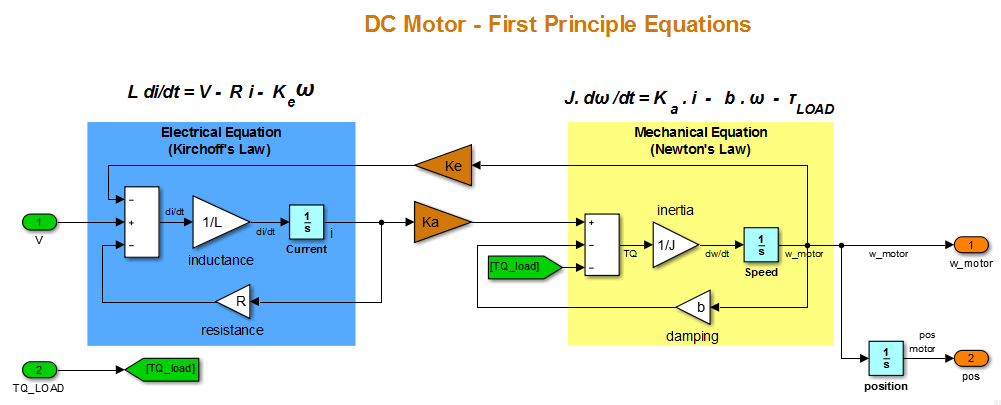

`Bradley Horton : 01-Jun-2016, bradley.horton@mathworks.com.au`

## Read in timeseries MEASUREMENT data from XLS file

Our first step is to import the time series measurement data from the Excel file, into MATLAB.

MOTOR_MEAS_DATA = readtable('bh_MEAS_DATA_MOTOR.xlsx', ...
                           'Sheet', 'MOTOR_ONLY_STAIRS');                   

There's alot of time samples in this file, so here's a peak at just a few rows of data:

MOTOR_MEAS_DATA(106:110,:)                         

ans =     time_secs    IN_VOLTS    OUT_W_RAD_PER_SEC
    _________    ________    _________________

    1.05         1           192.98           
    1.06         1           197.26           
    1.07         1           188.14           
    1.08         1           194.07           
    1.09         1           192.22           


Note that the data is imported into MATLAB as a ***table*** data type.  Have you seen these before? - they're kind of like a hybrid between a "standard" matrix and a user defined "struct". Very cool !

## Plot the time series measurement data

Before we do any parameter esimation, let's just plot our measurement data:

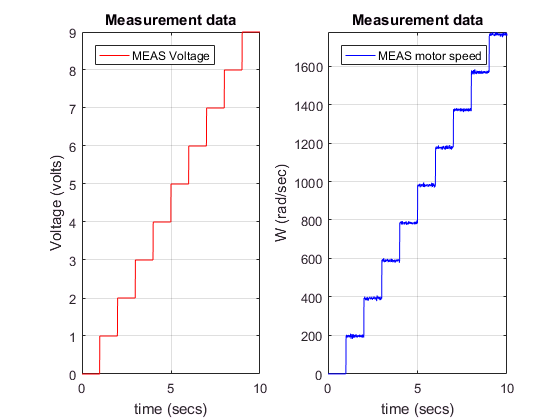

T = MOTOR_MEAS_DATA.time_secs; 
V = MOTOR_MEAS_DATA.IN_VOLTS;
W = MOTOR_MEAS_DATA.OUT_W_RAD_PER_SEC;

figure;
subplot(1,2,1);
    plot(T,V,'-r');
        xlabel('time (secs)');  ylabel('Voltage (volts)');
        axis('tight'); grid('on');
        legend('MEAS Voltage','Location','northwest');
        title(gca,'Measurement data')
subplot(1,2,2);
    plot(T,W,'-b');
        xlabel('time (secs)');  ylabel('W (rad/sec)'); 
        axis('tight'); grid('on');
        legend('MEAS motor speed','Location','northwest');
        title(gca,'Measurement data')

## Our Back-EMF constant $K_e$:

A 1st order approximation of a DC motor has the following form $\frac{\Omega(s)}{V(s)} = \frac{K_m}{T_ms + 1}$, $where$ 

- 
$$\Omega(s) = \mathcal{L}(\omega(t))$$


- 
$$K_m = \frac{K_a}{R.b \enspace + \enspace K_a.K_e}$$


- 
$$T_m = \frac{R.J}{R.b \enspace + \enspace K_a.K_e}$$


So if we make the assumption that the viscous damping term $b$is small AND that the rotor inertia term is small, then $K_m \rightarrow1/K_e$ and $T_m \rightarrow 0$.  So?, So with these assumptions our transfer function becomes $\Omega(s)/V(s) \longrightarrow \frac{K_m}{1} \longrightarrow 1/K_e $.  Let's see if we can see this in our data

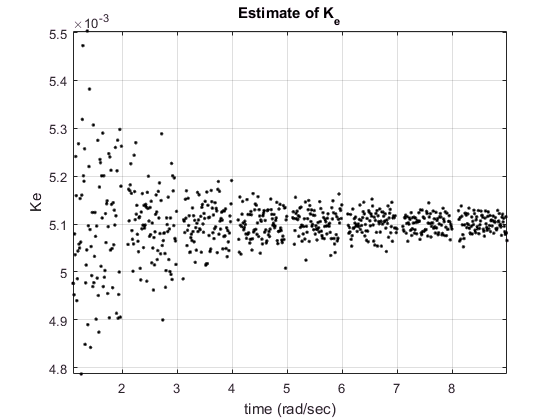


suspected_Ke = 1 ./ (W./V);
% we'll plot against time, so avoid the discontinuities at the step changes
tf_inds =  (T>1.1 & T<2) | (T>2.1 & T<3) | (T>3.1 & T<4) | (T>4.1 & T<5) | ...
           (T>5.1 & T<6) | (T>6.1 & T<7) | (T>7.1 & T<8) | (T>8.1 & T<9); 
figure;
plot(T(tf_inds), suspected_Ke(tf_inds), '.k');  axis('tight'); grid('on');
xlabel('time (rad/sec)'); ylabel('Ke');
title('Estimate of K_e')

So it looks like a reasonable estimate of of our back EMF constant$K_e$is:

mean(    suspected_Ke(tf_inds)  )

ans = 0.0051

## Getting ready for the parameter Estimation task - PART 1

Create some "nice" containers for the input and output time series data.

V_TS = timeseries(V,T);
W_TS = timeseries(W,T);

Note also the sample time of our measurement data:

ts   = T(2) - T(1);

## Getting ready for the parameter Estimation task - PART 2

Read in the Initial motor parameters from an Excel file:

init_mot_params_TAB = readtable('bh_MEAS_DATA_MOTOR.xlsx', 'Sheet', 'INITIAL_MOTOR_PARAMS', 'ReadRowNames',true)

Create separate variables for each parameter:

b  = init_mot_params_TAB{'b', 'Value'};
J  = init_mot_params_TAB{'J', 'Value'};
R  = init_mot_params_TAB{'R', 'Value'};
L  = init_mot_params_TAB{'L', 'Value'};
Ke = init_mot_params_TAB{'Ke','Value'};
Ka = init_mot_params_TAB{'Ka','Value'};

**Now let's use Simulink to do the parameter estimation task:**

Open the Simulink model <`bh_motor_for_param_estimation.slx`> and launch the parameter estimation project that we've created:

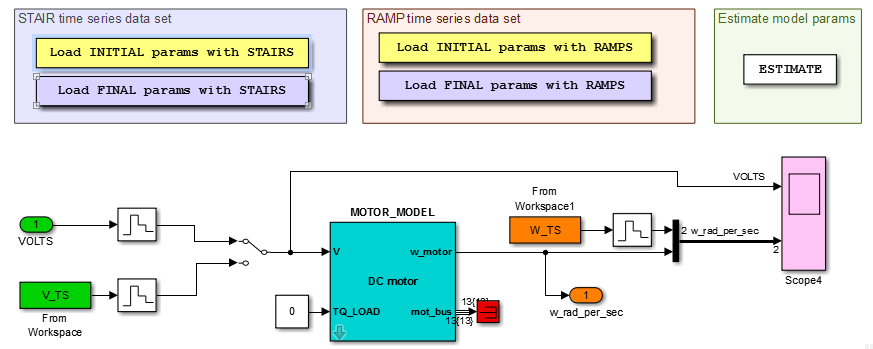

A typical workflow would be:

- Load initial parameter set

- Explore response

- Launch Parameter Estimation APP and run

NOTE: that the estimation task can be done via the APP, but it can also be done using function APIs - the API approach gives more access to tasks such as nonlinear constraints.

## So the final tuned parameters were:

final_mot_params_TAB = readtable('bh_MEAS_DATA_MOTOR.xlsx', 'Sheet', 'FINAL_MOTOR_PARAMS', 'ReadRowNames',true)

## Independent validation

Let's see how this "tuned" model performs when we use a separate independent time series measurement set.  Here is the validation data set:

*NB: go to the Simulink model and load this and then run the model*

NEW_MOTOR_MEAS_DATA = readtable('bh_MEAS_DATA_MOTOR.xlsx', ...
                               'Sheet', 'MOTOR_ONLY_RAMPS');
                       
Tv = NEW_MOTOR_MEAS_DATA.time_secs; 
Vv = NEW_MOTOR_MEAS_DATA.IN_VOLTS;
Wv = NEW_MOTOR_MEAS_DATA.OUT_W_RAD_PER_SEC;      

figure;
subplot(1,2,1);
    plot(Tv,Vv,'-r');
        xlabel('time (secs)');  ylabel('Voltage (volts)');
        axis('tight'); grid('on');
        legend('MEAS Voltage','Location','south');
        title(gca,'VALIDATION Measurement data')
subplot(1,2,2);
    plot(Tv,Wv,'-b');
        xlabel('time (secs)');  ylabel('W (rad/sec)'); 
        axis('tight'); grid('on');
        legend('MEAS motor speed','Location','south');
        title(gca,'VALIDATION Measurement data')
        

# **FYI !**

The parameter Estimation app is a "front end" for a collection of MATLAB functions that solve a nonlinear optimization problem.  An example of one of these optim solver functions is `sdo.optimize()`.

If you're curious you can read more about this function via:

doc sdo.optimize